# Controlling Chemical Bath Temperature

## Set up

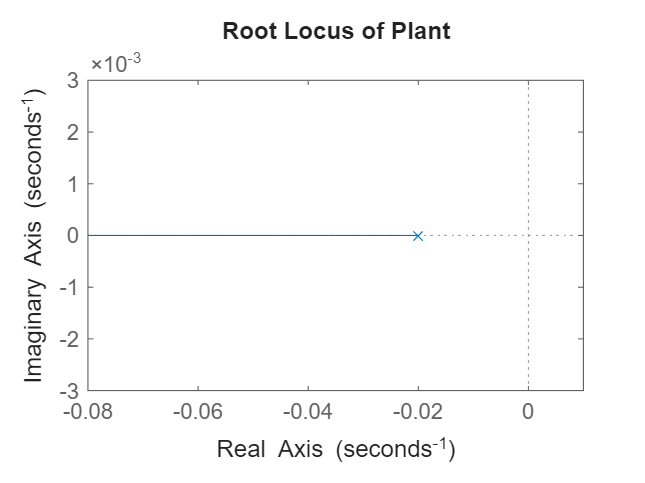

% Scenario: we need a temperature controlled bath for a chemistry
% experiment. The temperature of the bath is assumed to be constant
% throughout by use of a magnetic stirrer. There is a constant flow of
% water into the bath through a long pipe, so there is a convective time
% delay of 12 seconds. The baseline temperature for the bath is 35C. The
% maximum and minimum possible temperatures for the bath is 50c and 10c
% respectively. The goal of this exercise is to determine the K value for
% the proportional controller in order to minimise settling time. 
d=12; 
a0=0.02; % just a constant in the governing equation
ys= pade(d,2); % second order pade delay approximation
us= tf(1,[1/a0 1] ); % plant transfer function
gs= ys(1,1)*us; % plant transfer function accounting delay
figure(1), rlocus(gs), title('Root Locus of Plant');

Tmin= 10;Tmax=50;Taim=45;Taiml= 45-0.5;Taimu=45-0.5;Tstart=35;
% From the root locus of the plant, we can see that the system has one
% negative real pole. 

## Proportional Controller K=1

dsk1= 1; % proportional controller
oltf_k= dsk1*gs; % open loop transfer function of plant and controller
cltf_k= feedback(oltf_k,1); % closed loop transfer function with negative feedback
ssgain_k= dcgain(cltf_k) % steady state gain so that the loop prefactor can be determined

ssgain_k = 0.5000

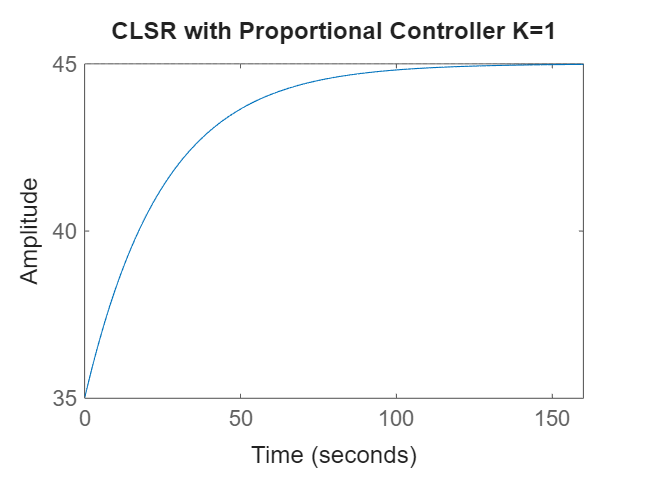

stepexp_k= Tstart+ (1/ssgain_k)*Tmin*cltf_k; % closed loop transfer function accounting for loop prefactor, baseline temperature (35c) and step temperature (10c)
figure(2),step(stepexp_k), title('CLSR with Proportional Controller K=1');

stepinfo(cltf_k)

ans = struct with fields:
         RiseTime: 54.9252
    TransientTime: 97.8019
     SettlingTime: 97.8019
      SettlingMin: 0.4523
      SettlingMax: 0.4997
        Overshoot: 0
       Undershoot: 0
             Peak: 0.4997
         PeakTime: 183.0555

% A large negative real root should mean rapid settling time. The control strategy is to increase K by a factor of 10. 

## Proportional Controller K=10

dsk10= 10;
oltf_k10= dsk10*gs;
cltf_k10= feedback(oltf_k10,1);
ssgain_k10= dcgain(cltf_k10)

ssgain_k10 = 0.9091

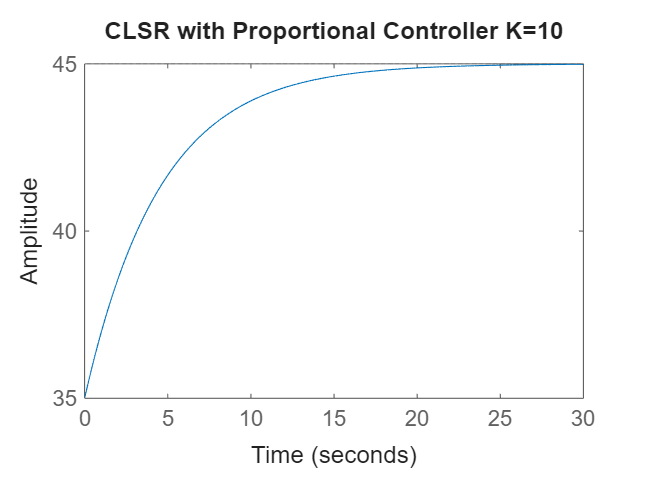

stepexp_k10= Tstart+ (1/ssgain_k10)*Tmin*cltf_k10;
figure(3),step(stepexp_k10), title('CLSR with Proportional Controller K=10');

stepinfo(cltf_k10)

ans = struct with fields:
         RiseTime: 9.9864
    TransientTime: 17.7822
     SettlingTime: 17.7822
      SettlingMin: 0.8223
      SettlingMax: 0.9085
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9085
         PeakTime: 33.2828

## Proportional Controller K=100

dsk100= 100;
oltf_k100= dsk100*gs;
cltf_k100= feedback(oltf_k100,1);
ssgain_k100= dcgain(cltf_k100)

ssgain_k100 = 0.9901

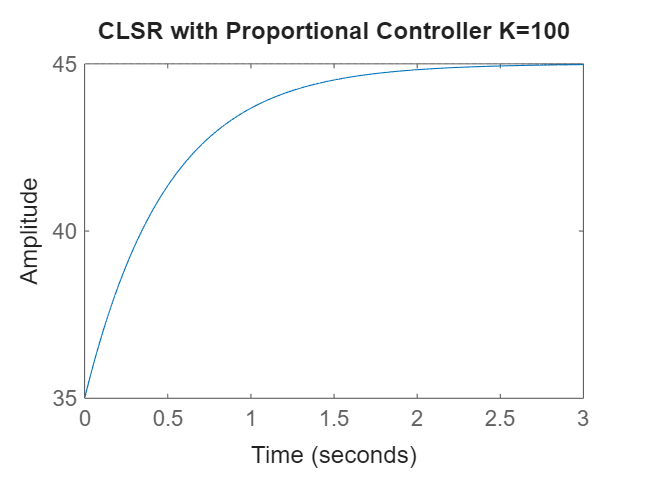

stepexp_k100= Tstart+ (1/ssgain_k100)*Tmin*cltf_k100;
figure(4),step(stepexp_k100), title('CLSR with Proportional Controller K=100');

stepinfo(cltf_k100)

ans = struct with fields:
         RiseTime: 1.0876
    TransientTime: 1.9367
     SettlingTime: 1.9367
      SettlingMin: 0.8955
      SettlingMax: 0.9894
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9894
         PeakTime: 3.6249

## Proportional Controller K=1000

dsk1000= 1000;
oltf_k1000= dsk1000*gs;
cltf_k1000= feedback(oltf_k1000,1);
ssgain_k1000= dcgain(cltf_k1000)

ssgain_k1000 = 0.9990

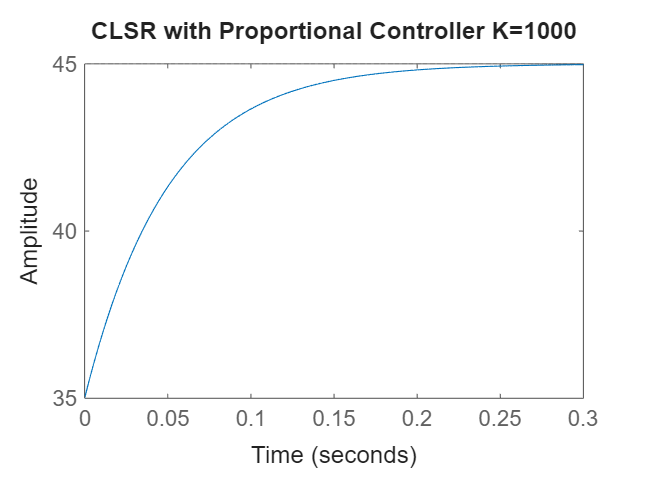

stepexp_k1000= Tstart+ (1/ssgain_k1000)*Tmin*cltf_k1000;
figure(5),step(stepexp_k1000), title('CLSR with Proportional Controller K=1000');

stepinfo(cltf_k1000)

ans = struct with fields:
         RiseTime: 0.1097
    TransientTime: 0.1954
     SettlingTime: 0.1954
      SettlingMin: 0.9036
      SettlingMax: 0.9983
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9983
         PeakTime: 0.3657

## Proportional Controller K=10000

dsk10000= 10000;
oltf_k10000= dsk10000*gs;
cltf_k10000= feedback(oltf_k10000,1);
ssgain_k10000= dcgain(cltf_k10000)

ssgain_k10000 = 0.9999

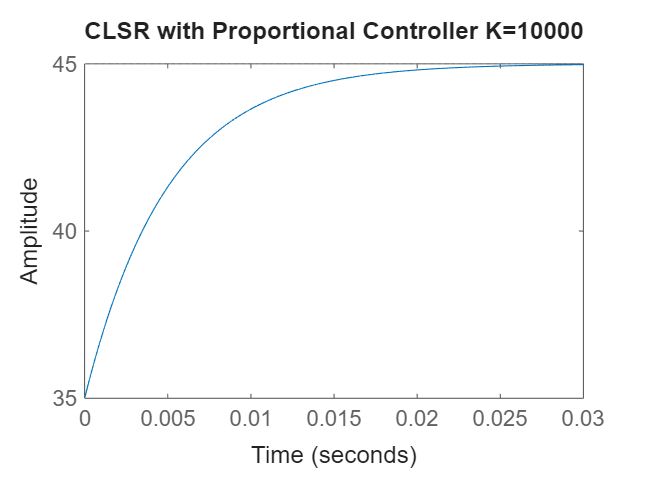

stepexp_k10000= Tstart+ (1/ssgain_k10000)*Tmin*cltf_k10000;
figure(5),step(stepexp_k10000), title('CLSR with Proportional Controller K=10000');

stepinfo(cltf_k10000)

ans = struct with fields:
         RiseTime: 0.0110
    TransientTime: 0.0196
     SettlingTime: 0.0196
      SettlingMin: 0.9044
      SettlingMax: 0.9992
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9992
         PeakTime: 0.0366

% From this exercise, it stands to reason that as K increases
% exponentially, the settling time will decrease exponentially.